# Projective Geometry 

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-11-20

## Quiz1: Line passes through two points (0,1) and (1,2)

pt1 = [0 1];
pt2 = [1 2];

slope = (pt2(2)-pt1(2))/(pt2(1)-pt1(1));
l1 = [slope -1 -slope*pt1(1)+pt1(2)]

l1 =      1    -1     1


l2 = cross([pt1 1], [pt2 1])

l2 =     -1     1    -1


## Quiz2: Intersection point ($p_x$, $p_y$) of the two lines $l_1$ and $l_2$ 

$l_1$passes trhough two distinct points, (0,1) and (1,2). 

$l_2$passes trhough two distinct points, (4,0) and (5,3). 

% method 1 (using the homogeneous coordinate representaion)
l1 = cross([0,1,1]',[1,2,1]');
l2 = cross([4,0,1]',[5,3,1]');
x = cross(l1,l2);
px = x(1)/x(3);
py = x(2)/x(3);
fprintf('(px,py) = (%1.2f, %1.2f) \n', px, py);

(px,py) = (6.50, 7.50) 


% method 2
% Line-line intersection
% https://en.wikipedia.org/wiki/Line%E2%80%93line_intersection

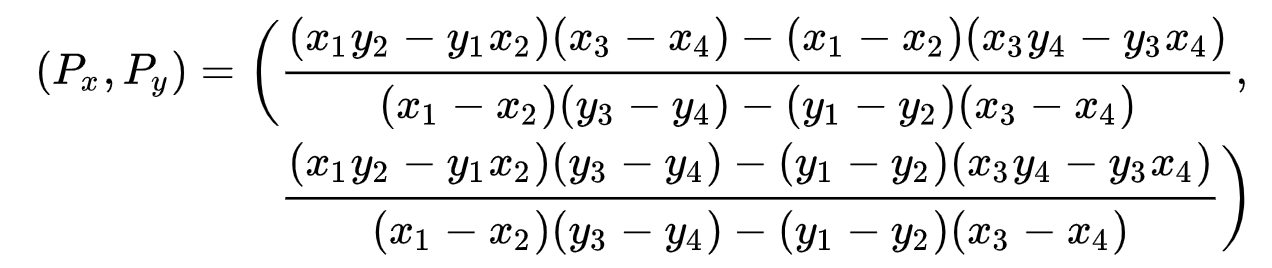

denom = (0-1)*(0-3)-(1-2)*(4-5);
numerx = (0*2-1*1)*(4-5)-(0-1)*(4*3-0*3);
numery = (0*2-1*1)*(0-3)-(1-2)*(4*3-0*3);

px = numerx/denom; 
py = numery/denom;
fprintf('(px,py) = (%1.2f, %1.2f) \n', px, py);

(px,py) = (6.50, 7.50) 


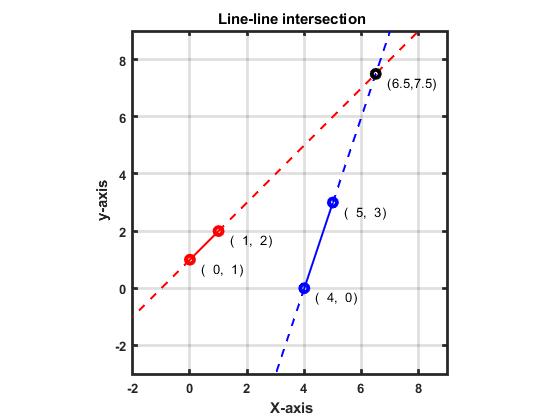

figure(1);
plot([0 1], [1, 2], 'or', 'linewidth', 3); hold on;
line([0 1], [1, 2],  'linewidth', 1.5, 'Color', 'r');
plot([4 5], [0, 3], 'ob', 'linewidth', 3);
line([4 5], [0, 3],  'linewidth',  1.5, 'Color', 'b'); 

line([1 8], [2, 9], 'Color', 'r', 'linewidth',  1.5, 'LineStyle', '--');
line([5 7], [3, 9], 'Color', 'b', 'linewidth',  1.5,  'LineStyle', '--'); 
line([0 -2], [1, -1], 'Color', 'r', 'linewidth',  1.5,  'LineStyle', '--');
line([4 3], [0, -3], 'Color', 'b',  'linewidth',  1.5, 'LineStyle', '--'); 

plot(6.5,7.5,'ok', 'linewidth', 3); 

text([0 1 4 5 6.5],[1 2 0 3 7.5],strcat('   (',num2str([0 1 4 5 6.5]'),',',num2str([1 2 0 3 7.5]'),')'),...
     'horiz','left','vert','top');hold off;

axis equal;grid on;
title('\bf Line-line intersection');
xlabel('\bf X-axis');xlim([-2 9]);
ylabel('\bf y-axis');ylim([-3 9]);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')

## Quiz3: Given a conic $\frac{x^2 }{6^2 }+\frac{y^2 }{3^2 }-1=0$ (ellipse), compute a tagential line to this conic at ($\left.\sqrt{20},2\right)$and its intersection point with x-axis, ($p_x$, $p_y$). 

% method 1 (using the homogeneous coordinate representaion)
% ax1^2 + bx1x2 + cx2^2 + dx1x3 + ex2x3 + fx3^2 = 0

a = 1/6/6;
b = 0;
c = 1/3/3;
d = 0;
e = 0;
f = -1;

conic = [a b/2 d/2; b/2 c e/2; d/2 e/2 f];
m = sqrt(20);
n = 2;
lmn = conic*[m;n;1]

lmn =     0.1242
    0.2222
   -1.0000



% alpha*x + beta*y + 1 = 0
alpha = lmn(1)/lmn(3);
beta = lmn(2)/lmn(3);
fprintf('line euqation: %fx+%fy+1=0 \n', alpha, beta);

line euqation: -0.124226x+-0.222222y+1=0 



% x-axis: y=0
lxa  = [0 1 0];

x = cross(lmn, lxa);
px = x(1)/x(3);
py = x(2)/x(3);
fprintf('(px,py) = (%1.2f, %1.2f) \n', px, py);

(px,py) = (8.05, -0.00) 


% method 2
% https://math.stackexchange.com/questions/958046/find-the-equation-of-the-tangent-line-to-the-ellipse-at-the-given-point

a = 6;
b = 3;
m = sqrt(20);
n = 2;

% alpha*x + beta*y + 1 = 0
alpha = m/a/a * -1;
beta = n/b/b * -1;
fprintf('line euqation: %fx+%fy+1=0 \n', alpha, beta);

line euqation: -0.124226x+-0.222222y+1=0 



px = -1/alpha;
py = 0;
fprintf('(px,py) = (%1.2f, %1.2f) \n', px, py);

(px,py) = (8.05, 0.00) 


figure(2);
x = -6:0.01:6;
y = sqrt((1-x.*x/36)*9);
plot(x,y,'-b', 'linewidth', 1.5);hold on;
plot(x,-y,'-b', 'linewidth', 1.5);

x_line = -10:0.01:12;
y_line = (-1-alpha*x_line)/beta;
plot(x_line,y_line,'--r', 'linewidth', 1.5);

plot(x_line,zeros(numel(x_line),1),'-k', 'linewidth', 1.5);

plot(sqrt(20),2,'ok', 'linewidth', 3); 
h=text(sqrt(20),2,'     ($$\sqrt{20}$$, 2)', 'horiz','left','vert','bottom');
plot(8.05,0,'ok', 'linewidth', 3); 
text(8.05,0,strcat('     (',num2str(8.05'),',',num2str(0'),')'), 'horiz','left','vert','bottom');hold off;

axis equal;grid on;

title('\bf Conic');
xlabel('\bf X-axis');xlim([-7 12]);
ylabel('\bf y-axis');ylim([-4 4]);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');
set(h,'Interpreter','latex'); 